# TARATURA DEL GIUNTO 1

clear all
close all
clc

dopo aver caricato il modello del giuntoi, tramite la funzione damp si identificano le frequenze per trovare le frequenze di risonnza del modello

load file_mat_init\ide_modelli_scara.mat
G2 = modello_continuo_q2;
dataG2=damp(G2)

dataG2 =    73.6222
  712.8826
  712.8826
  986.8044
  986.8044


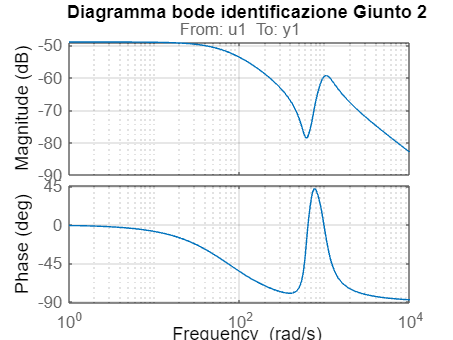

figure
bode(G2)
grid on
title('Diagramma bode identificazione Giunto 2')

# TARATURA LOOP INTERNO CONTROLLORE PI

# e_vel -> PI -> FILTRO NOTCH -> FILTRO PASSA BASSO -> u

## **FILTRO NOTCH**

**avendo il sistema un picco di risonanza all wn = 671.4003 rad/s si è deciso di inserire un filtro notch per abbassare il picco di risonanza.**


$$\textrm{Fn}\left(s\right)=\frac{s^{2\;} +2\cdot x{\textrm{ci}}_{\textrm{z2}} \cdot Wn_{\textrm{notch2}} \cdot s+Wn_{\textrm{notch2}}^2 }{s^{2\;} +2\cdot x{\textrm{ci}}_{\textrm{z2}} \cdot Wn_{\textrm{notch2}} \cdot s+Wn_{\textrm{notch2}}^2 }$$


Di seguito viene progettato il filtro notch elimina banda con una frequenza vicina a 671 rad/s per rendere il diagramma di bode del filtro in serie al sistema più smooth

Poi per tentativi, sono stati decisi i valori "ottimali" di xci_z e xci_p che indicano la selettività del filtro notch

Wn_notch2 = 986.8;
xci_z2=0.2; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p2=0.7;
s=tf('s');
notch2=(s^2+2*xci_z2*Wn_notch2*s+Wn_notch2^2)/(s^2+2*xci_p2*Wn_notch2*s+Wn_notch2^2);

Verifica del filtro mediante l'utilizzo dei diagrammi di bode

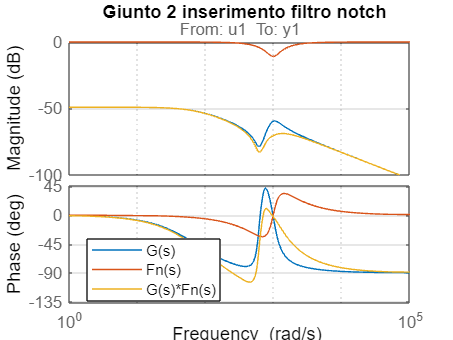

figure
bode(G2)
hold on
bode(notch2)
grid on
bode(notch2*G2)
hold off
legend('G(s)','Fn(s)','G(s)*Fn(s)','Location','best')
title('Giunto 2 inserimento filtro notch ')

## FILTRO PASSA BASSO

Prima di procedere con la taratura del controllore PI per il loop interno si inserisce un filtro passa basso per attenuare le alte frequenze dell'azione di controllo che possono essere dovute dall'influenza del rumore del sul sensore


$$F\left(s\right)=\frac{1}{\textrm{Tf}\cdot \;s+1}$$


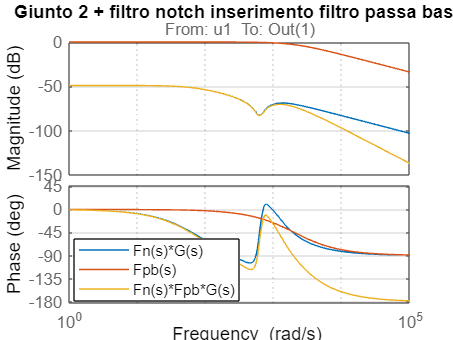

Tf2_vel = (1/2000);
F = tf(1,[Tf2_vel 1]);

figure
bode(notch2*G2)
hold on 
bode(F)
bode(notch2*F*G2)
legend('Fn(s)*G(s)','Fpb(s)','Fn(s)*Fpb*G(s)','Location','best')
grid on
hold off
title('Giunto 2 + filtro notch inserimento filtro passa basso ')

## CONTROLLORE PI

G2nf= notch2*F*G2;

la wc desiderata è stata calcola in maniera tale che il picco nella zona di risonanza sia attenuato di almeno 6dB

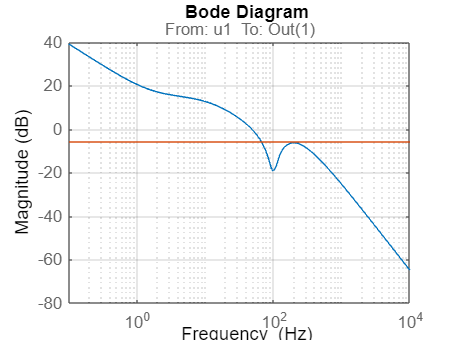

wc_des=300;

w_vector=logspace(-4,10)'; % [10^-3,10^3]

wi_vel2 = wc_des/30; %rad/s
Ti_vel2 = 1/wi_vel2; %s
s = tf('s');
Kp2_vel=(1/abs(freqresp(G2nf,wc_des)));
Ki2_vel = Kp2_vel/Ti_vel2;
Kaw2 = Ki2_vel/Kp2_vel; % per anti-windup
C2pi=tf([Kp2_vel Ki2_vel],[1 0]);
L2 = C2pi*G2nf;
h = bodeplot(L2);
setoptions(h,'FreqUnits','Hz','PhaseVisible','off','grid','on');
hold on 
bodeplot(tf(0.50115))%valore corrispondente a  -6.0006dB

C_fr=freqresp(L2,w_vector);
S_fr=1./(1+(C_fr)); % S = 1/(1+L) sensitivity function
max(abs(S_fr))

ans = 1.0685

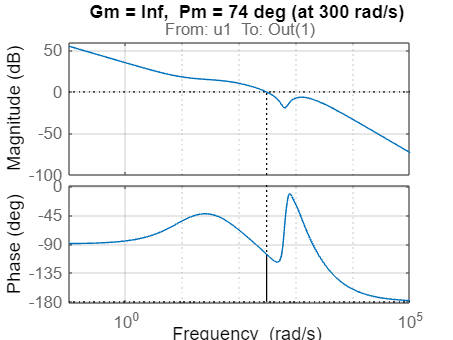

figure
margin(L2)
grid on

## Verifica con STEP

per sicurezza si verifica che la risposta allo scalino dell'anello interno sia come ci aspettiamodalla taratura effettuata.

la funzione dell'anello interno è calcolata come segue:


$$\textrm{L1ret}=\frac{\textrm{PI}\cdot \textrm{Fn}\cdot \textrm{Fpb}\cdot \textrm{G1}}{1+\textrm{PI}\cdot \textrm{Fn}\cdot \textrm{Fpb}\cdot \textrm{G1}}=\frac{\textrm{L1}}{1+\textrm{L1}\;}\Rightarrow \;\textrm{feedback}\left(\textrm{L1},1\right)$$


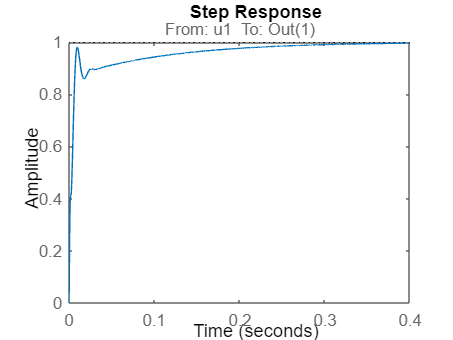

L2ret = feedback(L2,1);
figure
step(L2ret)

# TARATURA LOOP ESTERNO CONTROLLORE P

# e_pos -> P -> FILTRO PASSA BASSO -> u_pos

per passare dalla velocità alla posizone introduciamo un integrale mediante 1/s e grafichiamo il sistema per semlicità per la  fase di taratura

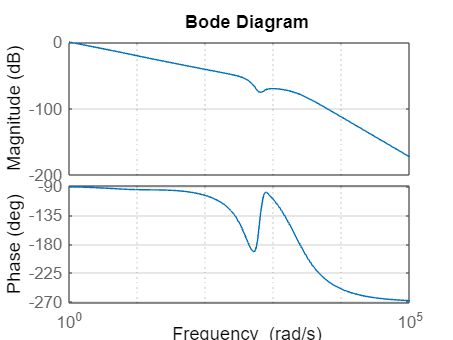

G2e = L2ret*1/s;
bode(G2e)
grid on

## FILTRO PASSA BASSO

Prima di procedere con la taratura del controllore P per il loop esterno si inserisce un filtro passa basso per attenuare le alte frequenze dell'azione di controllo che possono essere dovute dall'influenza del rumore del sul sensore


$$F\left(s\right)=\frac{1}{\textrm{Tf}\cdot \;s+1}$$


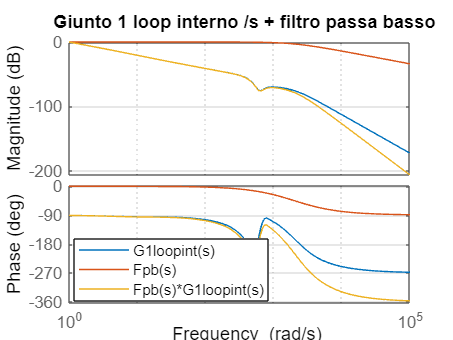

Tf2_pos = (1/2000);
F2 = tf(1,[Tf2_pos 1]);

figure
bode(G2e)
hold on 
bode(F2)
bode(F2*G2e)
legend('G1loopint(s)','Fpb(s)','Fpb(s)*G1loopint(s)','Location','best')
grid on
hold off
title('Giunto 1 loop interno /s + filtro passa basso ')

## **CONTROLLORE P -> LOOP ESTERNO **

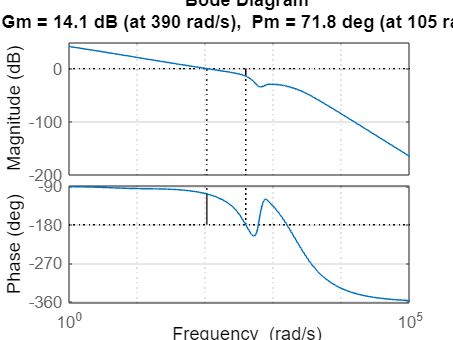

wc_esterno = 105;
Kp2_pos=1/abs(freqresp(F2*G2e,wc_esterno));

Cp2=Kp2_pos;

figure
margin(Cp2*F2*G2e)
grid on

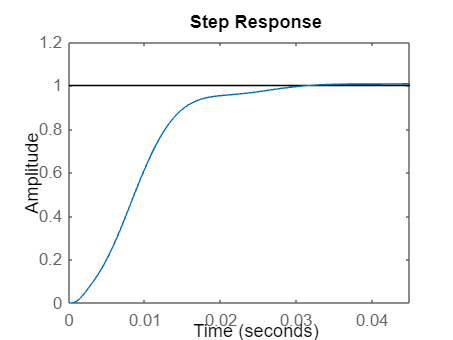

step(feedback(Cp2*F2*G2e,1))

%check della stabilità
C_fr=freqresp(Cp2*F2*G2e,w_vector);
S_fr=1./(1+(C_fr)); % S = 1/(1+L) sensitivity function
max(abs(S_fr))

ans = 1.2841

Sezione di salvataggio dei parametri trovati nella fase di taratura

save("ctrl2.mat","Kp2_pos","Kp2_vel","Ki2_vel","Kaw2","Tf2_vel","Tf2_pos","Wn_notch2","xci_p2","xci_z2")